Problem 1

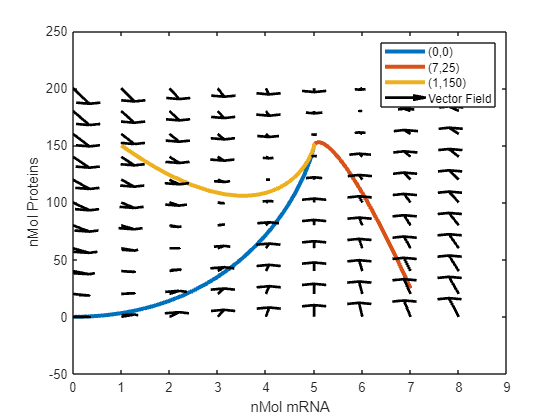

pars(1).a = 5; % nM/hr
pars(1).b = 1; % /hr
pars(1).r = 30; % proteins/(mRNA*hr)
t0 = 0; % Time to start
tf = 24; % Final time
% Define a vector of protein and mRNA values
pvec = 0:20:200;
mvec = 0:1:8;

[t,x] = ode45(@(t,x) proteinproduction(t,x,pars(1)),[t0 tf],[0,0]);
plot(x(:,1),x(:,2),'LineWidth',3);
hold on
[t,x] = ode45(@(t,x) proteinproduction(t,x,pars(1)),[t0 tf],[7,25]);
plot(x(:,1),x(:,2),'LineWidth',3);
[t,x] = ode45(@(t,x) proteinproduction(t,x,pars(1)),[t0 tf],[1,150]);
plot(x(:,1),x(:,2),'LineWidth',3);
xlabel('nMol mRNA','FontSize',20)
ylabel('nMol Proteins','FontSize',20)
set(gca,'FontSize',10)
dmdt = @(m) pars.a - pars.b.*m;
dpdt = @(m,p) pars.r.*m-pars.b.*p;
[MM,PP] = meshgrid(mvec,pvec);
quiver(MM,PP,dmdt(MM),dpdt(MM,PP),'k','MaxHeadSize',.015,'LineWidth',2);
hold off
legend('(0,0)','(7,25)','(1,150)','Vector Field')

All of the 3 parameters will start out at their initial conditions, but they will eventually converge to one point. Depending on their initial conditions, the mRNA and protein concentrations won't always increase if their starting condition is greater than the converging point. All 3 starting conditions should converge to (5, 150), or 5 nMol of mRNA and 150 nMol of proteins. 

Problem 2

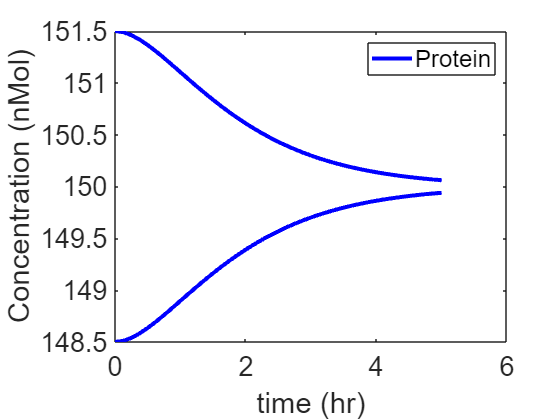

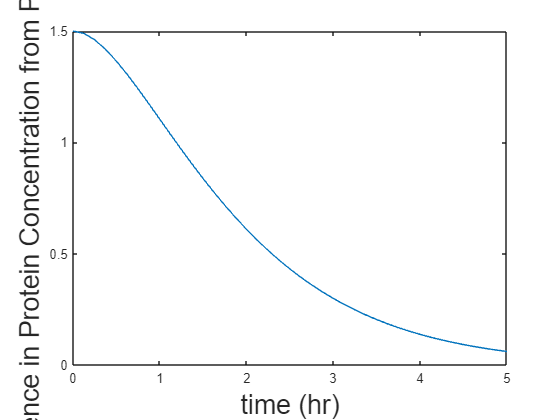

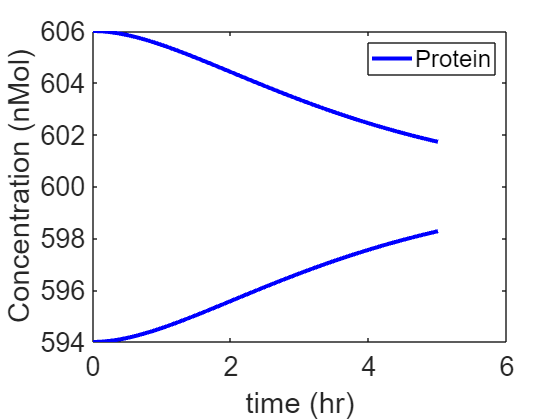

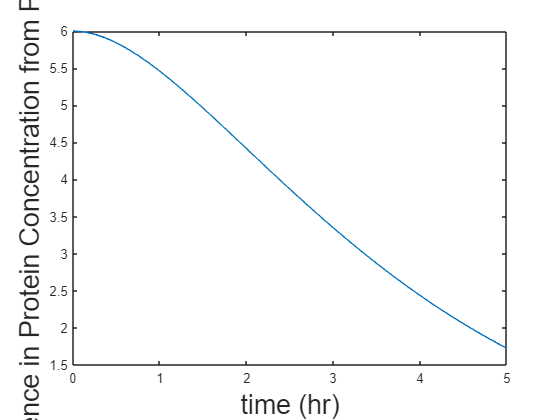

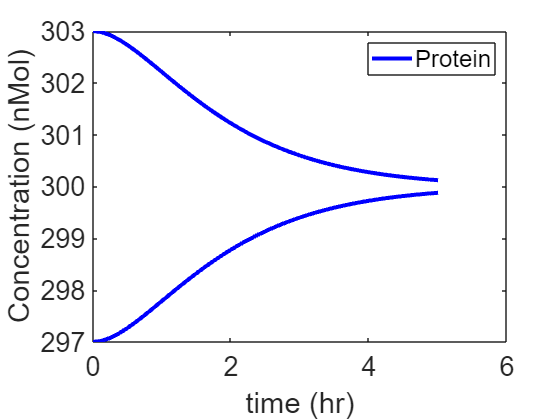

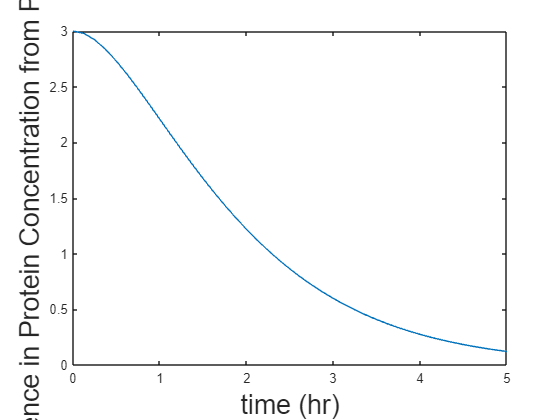

pars2(1).a = 5;
pars2(1).b = 1;
pars2(1).r = 30;

pars2(2).a = 5;
pars2(2).b = .5;
pars2(2).r = 30;

pars2(3).a = 10;
pars2(3).b = 1;
pars2(3).r = 30;

for i = 1:length(pars2)
    figure();
    pstar = pars2(i).r*pars2(i).a/pars2(i).b^2;
    mstar = pars2(i).a/pars2(i).b;
    pperturb = pstar.*.01;
    mperturb = mstar.*.01;
    x0 = [mstar+mperturb pstar+pperturb];
    x00 = [mstar-mperturb pstar-pperturb];
    t0 = 0;
    tf = 5;
    [tt,xx] = ode45(@proteinproduction,[t0 tf],x0,[],pars2(i));
    [ttt, xxx] = ode45(@proteinproduction,[t0 tf],x00,[],pars2(i));
    plot(tt,xx(:,2),'b','LineWidth',3)
    hold on
    plot(tt,xxx(:,2),'b','LineWidth',3)
    hold off
    xlabel('time (hr)','FontSize',20)
    ylabel('Concentration (nMol)','FontSize',20)
    legend('Protein')
    set(gca,'FontSize',20)
    figure();
    plot(tt, xx(:,2) - pstar)
    xlabel('time (hr)','FontSize',20)
    ylabel('Difference in Protein Concentration from P* (nMol)','FontSize',20)
end

For each parameter set, all of the graphs should roughly resemble the same shape wherein they all start from a perturbed point and then eventually converge to equilibrium, following exponential decay. However, because each parameter set is slightly different, they all have a different pertubation and equilibrium point, as well as different rates of convergence. This is evident in the graph depicting the difference in Protein Concentration from P* over time. Although each curve roughly follows the same trajectory, they all start out at different protein concentration levels from P* and also do not reach the same difference in concentration levels at t = 5.

(a = 5, b = 1, r = 30)

Fixed point: p* = ra/b^2 = 150 nMol

Rate of return: -b = -1 nMol/hr

(a = 5, b = 0.5, r = 30)

Fixed point: 600 nMol 

Rate of return: -.5 nMol/hr

(a = 10, b = 1, r = 30)

Fixed point: 300 nMol

Rate of return: -1 nMol/hr

Functions

function dxdt = proteinproduction(t,x,pars)
m = x(1);
p = x(2);
dmdt = pars.a - pars.b*m;
dpdt = pars.r*m-pars.b*p;
dxdt = [dmdt; dpdt];
end